ParentDir = "D:\YuLab\Work\GPS\Video";
AnmDir = uigetdir(ParentDir, "Choose animal directionory");

TrajGroupClassFile = dir(AnmDir+"\*TrajGroupClass*.mat");
if length(TrajGroupClassFile)>1
    fprintf("More than one TrajGroupClass found");
    return;
end

load(fullfile(AnmDir, TrajGroupClassFile.name));


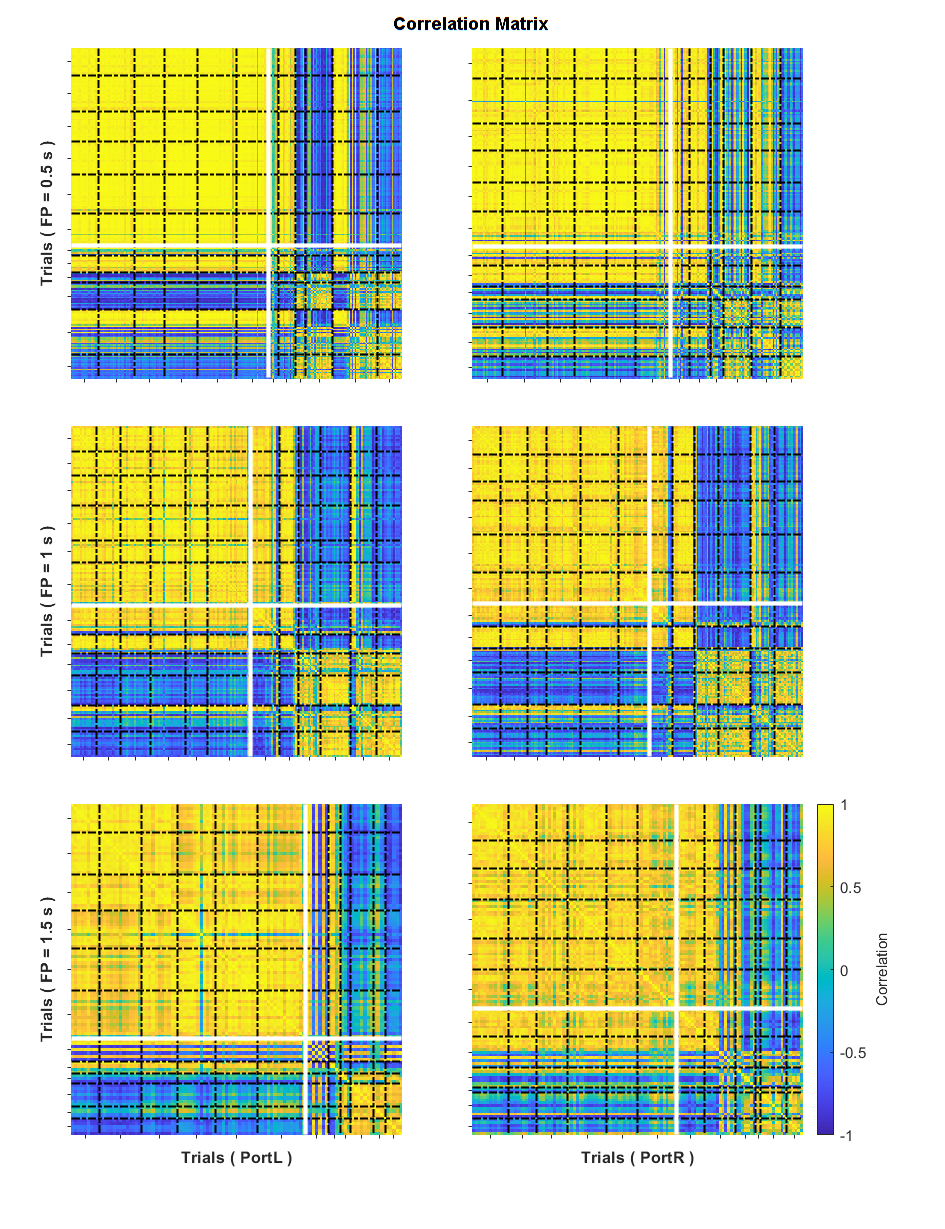

mycolormap = "parula";

fig_rsm = figure(51); clf(51);
set(fig_rsm, 'Units', 'Centimeters', 'Position', [1 1 20 26], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_rsm, 'units', 'normalized', 'position', [0.2 0.96 0.6 0.03],...
    'string', "Correlation Matrix", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for i = 1:3

    for j = 1:2

        ax_rsm = axes;
        set(ax_rsm, 'Units', 'Centimeters', 'Position', [1.5+8.5*(j-1) 18-8*(i-1) 7 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

        these_trials = find(obj.TrialInfo.Performance=="Correct" & obj.TrialInfo.PortChosen==obj.Ports(j) & obj.TrialInfo.FP==obj.MixedFPs(i) & obj.TrialInfo.Stage==1);

        these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
        sessions_control = obj.TrialInfo.Session(these_trials_control);
        sessions_control_id = unique(sessions_control);
        num_trials_control = zeros(length(sessions_control_id), 1);
        for k = 1:length(sessions_control_id)
            num_trials_control(k) = sum(sessions_control==sessions_control_id(k));
        end

        these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
        sessions_chemo = obj.TrialInfo.Session(these_trials_chemo);
        sessions_chemo_id = unique(sessions_chemo);
        num_trials_chemo = zeros(length(sessions_chemo_id), 1);
        for k = 1:length(sessions_chemo_id)
            num_trials_chemo(k) = sum(sessions_chemo==sessions_chemo_id(k));
        end

        session_seps = cumsum([num_trials_control; num_trials_chemo]) + 0.5;

        M = obj.AngleHeadMatIn([these_trials_control; these_trials_chemo], 100:100+1000*obj.MixedFPs(i));

        M_dist = corrcoef(M');

        colormap(mycolormap);
        imagesc(M_dist); clim([-1 1]);

        xline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
        yline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

        xline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'w', 'Alpha', 1);
        yline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'w', 'Alpha', 1);

        xlim([.5 length(these_trials)+.5]);
        ylim([.5 length(these_trials)+.5]);

        xticks(session_seps - [num_trials_control; num_trials_chemo] / 2); xticklabels([]);
        yticks(session_seps - [num_trials_control; num_trials_chemo] / 2); yticklabels([]);

        
        if j == 1
            ax_rsm.YLabel.String = "Trials ( FP = " + num2str(obj.MixedFPs(i)) + " s )";
            ax_rsm.YLabel.FontWeight = "Bold";
        end
        if i == 3
            ax_rsm.XLabel.String = "Trials ( Port" + obj.Ports(j) + " )";
            ax_rsm.XLabel.FontWeight = "Bold";
        end

    end

end

ax_cb = axes;
set(ax_cb, 'Units', 'Centimeters', 'Position', [13.5 2 5 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none');
cb = colorbar;
clim(ax_cb, [-1 1]);
cb.FontSize = 9;
cb.Label.String = "Correlation";
cb.Label.FontSize = 9;

save_name = "CorrMatrix_" + obj.ANM + "_" + obj.Task + mycolormap + ".jpg";
save_path = fullfile(AnmDir, save_name);
saveas(fig_rsm, save_path);

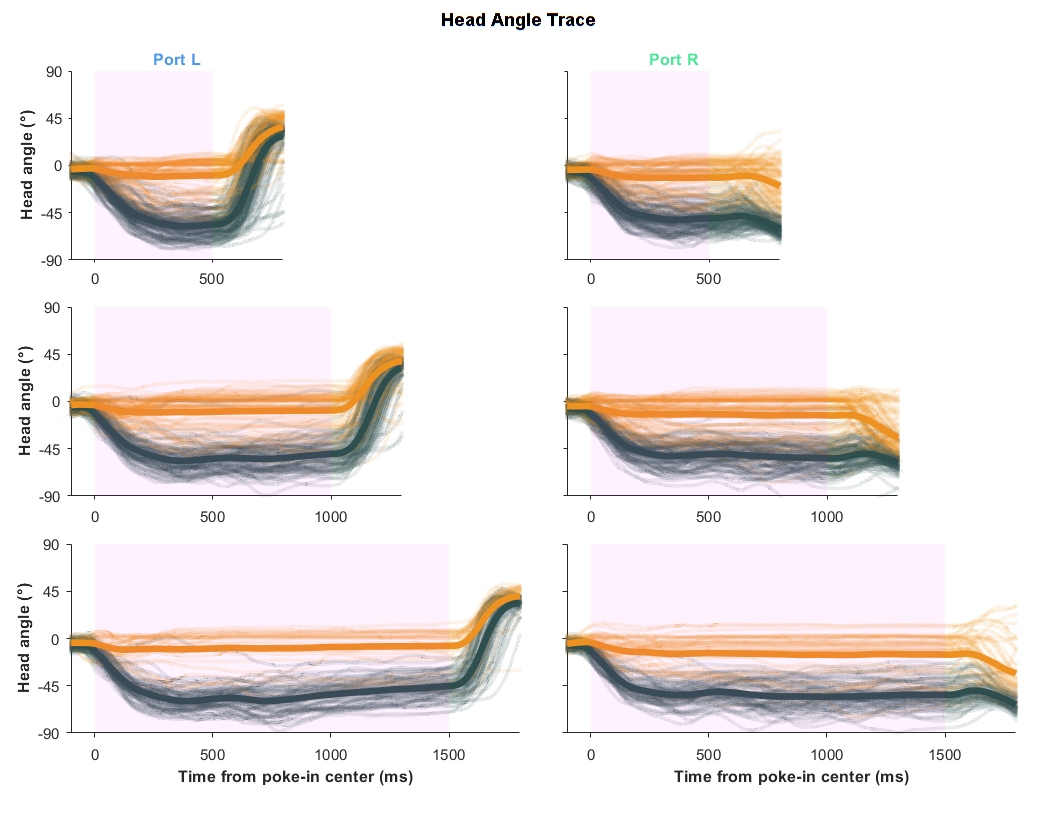

fig_trace = figure(52); clf(52);
set(fig_trace, 'Units', 'Centimeters', 'Position', [1 1 22 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_trace, 'units', 'normalized', 'position', [0.2 0.96 0.6 0.03],...
    'string', "Head Angle Trace", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

plot_height = 4;
plot_width  = [9 14 19] / 2;

for i = 1:3

    for j = 1:2

        ax_trace = axes;
        set(ax_trace, 'Units', 'Centimeters', 'Position', [1.5+10.5*(j-1) 12-5*(i-1) plot_width(i) plot_height], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        fp_begin = 0;
        fp_end   = 1000*obj.MixedFPs(i);

        these_trials = find(obj.TrialInfo.Performance=="Correct" & obj.TrialInfo.PortChosen==obj.Ports(j) & obj.TrialInfo.FP==obj.MixedFPs(i) & obj.TrialInfo.Stage==1);
        these_trials = these_trials(randperm(length(these_trials)));
        these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
        these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

        for k = 1:length(these_trials)
            switch obj.TrialInfo.Label(these_trials(k))
                case "Chemo"
                    color_this = GPSColor.Treat;
                case "Control"
                    color_this = GPSColor.Control;
            end
            patch(ax_trace, 'XData', [obj.TimePointsIn(1:100+1000*obj.MixedFPs(i)+300) nan], 'YData', [obj.AngleHeadMatIn(these_trials(k), (1:100+1000*obj.MixedFPs(i)+300)) nan], 'EdgeColor', color_this, 'EdgeAlpha', 0.1, 'LineWidth', 2)
        end

        plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.MixedFPs(i)+300), mean(obj.AngleHeadMatIn(these_trials_control, 1:100+1000*obj.MixedFPs(i)+300)), ...
            'Color', GPSColor.Control, 'LineWidth', 4)

        plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.MixedFPs(i)+300), mean(obj.AngleHeadMatIn(these_trials_chemo, 1:100+1000*obj.MixedFPs(i)+300)), ...
            'Color', GPSColor.Treat, 'LineWidth', 4)

        patch(ax_trace, 'XData', [fp_begin fp_end fp_end fp_begin], 'YData', [-90 -90 90 90], 'FaceColor', 'm', 'FaceAlpha', 0.05, 'EdgeColor', 'none')

        set(ax_trace, 'XLim', [-100 1000*obj.MixedFPs(i)+300], 'YLim', [-90 90], 'XTick', 0:500:1500, 'YTick', -90:45:90);
        if i == 3
            ax_trace.XLabel.String = "Time from poke-in center (ms)";
            ax_trace.XLabel.FontWeight = "bold";
        end
        if i == 1
            ax_trace.Title.String = "Port "+obj.Ports(j);
            ax_trace.Title.Color  = GPSColor.("Port"+obj.Ports(j));
            ax_trace.Title.FontWeight = "bold";
        end
        if j == 1
            ax_trace.YLabel.String = "Head angle (°)";
            ax_trace.YLabel.FontWeight = "bold";
        end
        if j == 2
            ax_trace.YTickLabel = [];
        end

    end

end
save_name = "HeadAngleTrace_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(AnmDir, save_name);
saveas(fig_trace, save_path);